依赖[统一实验分析作图v17.1.1](https://github.com/ShanghaitechGuanjisongLab/Unified-Experimental-Analysis-and-Figuring/releases)

行为学习曲线

% DataSetBas=UniExp.DataSet("\\Data-Server-1\个人数据\张天夫\202309\基本迁移行为v1.mat");
DataSetBas.Mice.Group=categorical(DataSetBas.Mice.Group);

SessionTableAL=DataSetBas.TableQuery(["Mouse","DateTime","Performance","Group"],Group="声光水",Design="LightWater");
SessionTableLL=DataSetBas.TableQuery(["Mouse","DateTime","Performance","Group"],Group="光声水",Design="LightWater");
SessionTableAA=DataSetBas.TableQuery(["Mouse","DateTime","Performance","Group"],Group="声光水",Design="AudioWater");
SessionTableLA=DataSetBas.TableQuery(["Mouse","DateTime","Performance","Group"],Group="光声水",Design="AudioWater");
SummaryL=UniExp.LearningSummarize([SessionTableAL;SessionTableLL]);SummaryA=UniExp.LearningSummarize([SessionTableAA;SessionTableLA]);

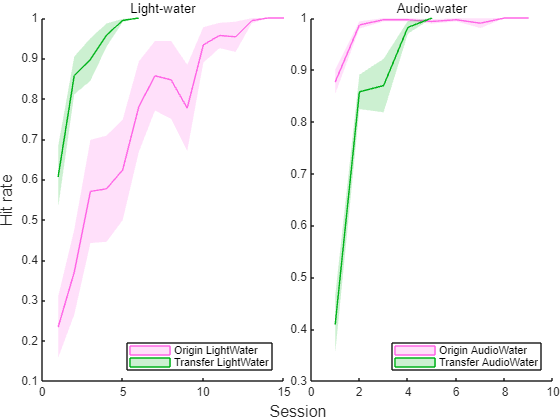

figure;
Colors=[1 0.4 0.9;0 0.7 0.1;0 0 0.1];
Layout=tiledlayout(1,2,TileSpacing='tight',Padding='tight');
nexttile;
Patches=MATLAB.Graphics.MultiShadowedLines(SummaryL.MeanCurve,SummaryL.SemCurve,EdgeColors=Colors(1:2,:));
legend(Patches,["Origin LightWater" "Transfer LightWater"],Location='southeast');title('Light-water');
nexttile;
Patches=MATLAB.Graphics.MultiShadowedLines(SummaryA.MeanCurve,SummaryA.SemCurve,EdgeColors=Colors(1:2,:));
legend(Patches,["Origin AudioWater" "Transfer AudioWater"],Location='southeast');title('Audio-water');
xlabel(Layout,'Session');
ylabel(Layout,'Hit rate');